clearvars;
close all;
N = 2^10;
T = 2.697200567700154e+001;
t0 = 0 ;

h = (T - t0)/(N-1);

U1 = zeros(2,N);
U1(1) = pi/3;
U1(2) = 0;

times = (t0:h:T);

for i = (1:N-1)
    U1(:,i+1) = RK2(times(i),U1(:,i),@fun,h);
end

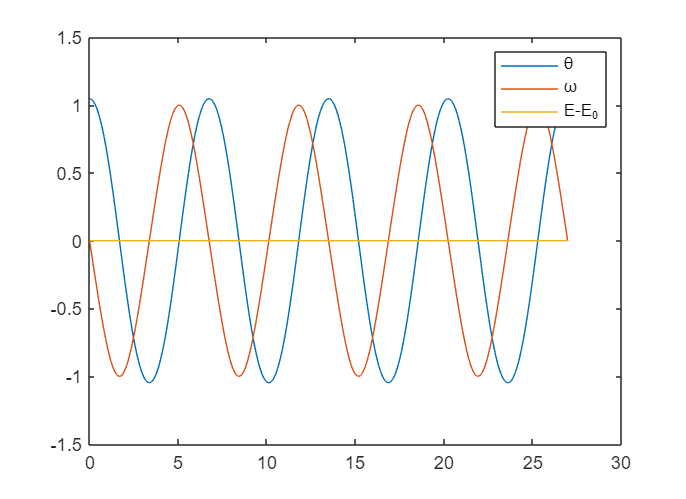





er  = U1(2,:).^2 / 2 + (cos(U1(1))-cos(U1(1,:)));

plot(times,U1(1,:))
hold on 
plot(times,U1(2,:))
plot(times,er)
legend('\theta','\omega','E-E_0')
hold off

function res = RK2(x0,u0,f,h)
    k1 = h* f(x0,u0,h);
    k2 = h* f(x0 + h/2, u0 + k1./2,h);
    u1 = u0 + 1/2*(k2+k1);
    res = u1;
end
function res = fun(x,u,h)
    theta = u(1);   
    w = u(2);
    res = [w,-sin(theta)]';
    
end

function res = fun2(x,u,h)
    theta = u(1);   
    w = u(2);
    
    res = [w - h/2 *sin(theta),-sin(theta) - h/2 * w*cos(theta)]';
end


